# Repeat Reunion Part 2: Stranger vs. Cagemate interactions by degu

conditionmat_f = RR_OrgData(rdb_rr, sumbehav, fem_pairs);
conditionmat_m = RR_OrgData(rdb_rr, sumbehav, mal_pairs);

colorcodes_fem = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_f = colorcodes_fem;
colorcodes_mal = [0 0 .75 ; 0 0 .4 ; .35 .35 1];
colorcodes_m = colorcodes_mal;

## 0. Distribution of data

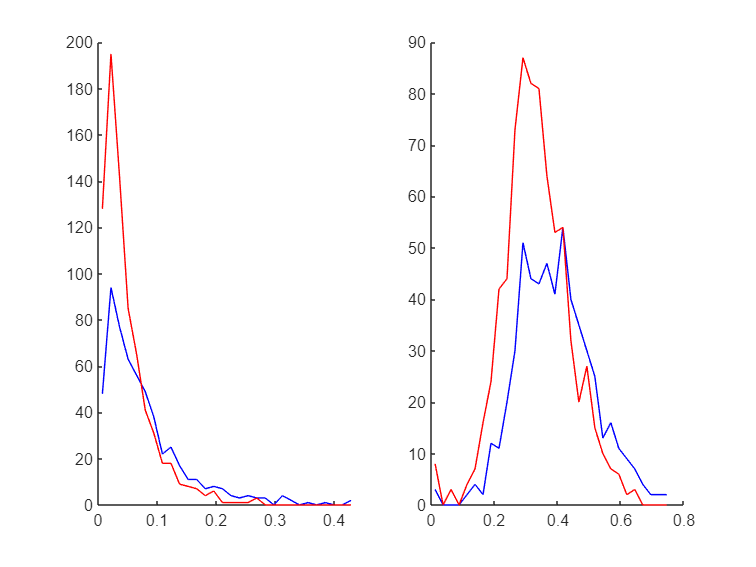



%first gauge the distribution--is it similar to the one of both degus?
%(answer is yes--good to use the cubed root)

fall = reshape(dtt(:,6:end),[],1);
mall = reshape(dttM(:,6:end), [], 1);

figure
subplot(1,2,1)
[am bm] = hist(mall, 30);
[af bf] = hist(fall, bm);

[amt bmt] = hist(mall.^(1/3), 30);
[aft bft] = hist(fall.^(1/3), bmt);

plot(bm,am, 'b')
hold on
plot(bf,af, 'r')
box off

subplot(1,2,2)
plot(bmt,amt, 'b')
hold on
plot(bft,aft, 'r')

box off

## I. Breakdown Cagemate vs. Stranger difference by individuals

Using 2-way repeated measures ANOVA. Requires "simple_mixed_anova"

allbyday_f = cat(3,dtt(:,6:10), dtt(:,11:15));
allbyday_m = cat(3,dttM(:,6:10), dttM(:,11:15));

allbyday_ct = [allbyday_f ; allbyday_m].^(1/3);
femmalvec = [ones(size(allbyday_f,1),1) ; 2*ones(size(allbyday_m,1),1)];


Combined model:


[tbl,rm] = simple_mixed_anova(allbyday_ct, femmalvec, {'exposureday' 'cagstr'}, {'sex'})

tbl = 12×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         120.95      1       120.95     2762.7    1.7078e-71    1.7078e-71    1.7078e-71    1.7078e-71
    sex                                0.54797      1      0.54797     12.517    0.00062876    0.00062876    0.00062876    0.00062876
    Error                               4.1153     94      0.04378                                                         

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [96×11 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {'sex'}
          BetweenModel: '1 + sex'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×10 table]
            Covariance: [10×10 table]


Female model

[tbl,rm] = simple_mixed_anova(allbyday_f, [], {'exposureday' 'cagstr'})

tbl = 8×8 table
                                        SumSq      DF       MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    __________    _______    __________    __________    __________    __________

    (Intercept)                          1.1457      1        1.1457     151.84    6.5564e-17    6.5564e-17    6.5564e-17    6.5564e-17
    Error                               0.38481     51     0.0075452                                                                   
    (Intercept):exposureday            0.015395      4     0.0038488     3.1546      0.015234       0.04155      0.0

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [52×10 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×10 table]
            Covariance: [10×10 table]


Male model

[tbl,rm] = simple_mixed_anova(allbyday_m, [], {'exposureday' 'cagstr'})

tbl = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                          2.1802      1       2.1802     210.76     3.512e-18     3.512e-18     3.512e-18     3.512e-18
    Error                               0.44481     43     0.010344                                                                   
    (Intercept):exposureday           0.0090539      4    0.0022635    0.73999       0.56593       0.52304       0.53231

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [44×10 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×10 table]
            Covariance: [10×10 table]


Now the figure


figure
sp1 = subplot(1,2,1)

sp1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


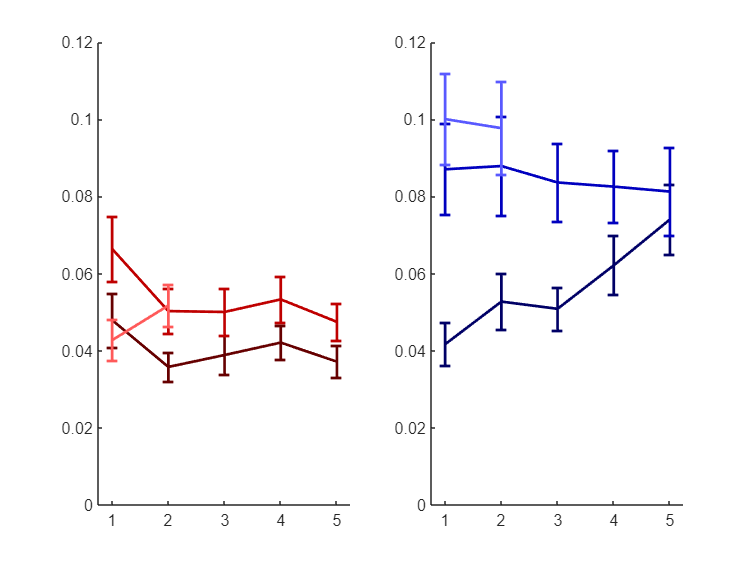

hold on

% randselect = randperm(size(dtt,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dtt(randselect(i), 6:10), 'Color', [1 .90 .90], 'LineStyle', '--');        
% 
%     plot(1:5, dtt(randselect(i), 11:15), 'Color', [1 .90 .90]);
% 
% %    plot(1:5, dtt(randselect(i), 16:20), 'Color', [1 .95 .90], 'LineStyle', ':');
% end

errorbar(1:5,nanmean(dtt(:, 6:10)), nanstd(dtt(:, 6:10))/sqrt(length(dtt)), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dtt(:, 11:15)), nanstd(dtt(:, 11:15))/sqrt(length(dtt)), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5 );
errorbar(1:2,nanmean(dtt(:, 16:17)), nanstd(dtt(:, 16:17))/sqrt(length(dtt)), 'Color', colorcodes_fem(3,:), 'LineWidth', 1.5 );
set(sp1, 'XLim', [.75 5.25]); 
box off

sp2 = subplot(1,2,2);
hold on

% randselect = randperm(size(dttM,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dttM(randselect(i), 6:10), 'Color', [.90 .90 1], 'LineStyle', '--');        
% 
%     plot(1:5, dttM(randselect(i), 11:15), 'Color', [.90 .90 1]);
% 
%  %   plot(1:5, dttM(randselect(i), 16:20), 'Color', [.9 .95 1], 'LineStyle', ':');
% end
errorbar(1:5,nanmean(dttM(:, 6:10)), nanstd(dttM(:, 6:10))/sqrt(length(dttM)), 'Color', colorcodes_mal(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dttM(:, 11:15)), nanstd(dttM(:, 11:15))/sqrt(length(dttM)), 'Color', colorcodes_mal(1,:), 'LineWidth', 1.5 );
errorbar(1:2,nanmean(dttM(:, 16:17)), nanstd(dttM(:, 16:17))/sqrt(length(dttM)), 'Color', colorcodes_mal(3,:), 'LineWidth', 1.5 );
set(sp1, 'XLim', [.75 5.25]); 


box off
set(sp2, 'XLim', [.75 5.25]); 
ylim1 = get(sp1, 'YLim');
ylim2 = get(sp2, 'YLim');
maxlims = max([ylim1 ; ylim2]);
set(sp1, 'YLim', [0 maxlims(2)-.0]);
set(sp2, 'YLim', [0 maxlims(2)-.0]);

## II. Breakdown of interactions by type

Taking male and female separately (j = 1 female, j = 2 male)

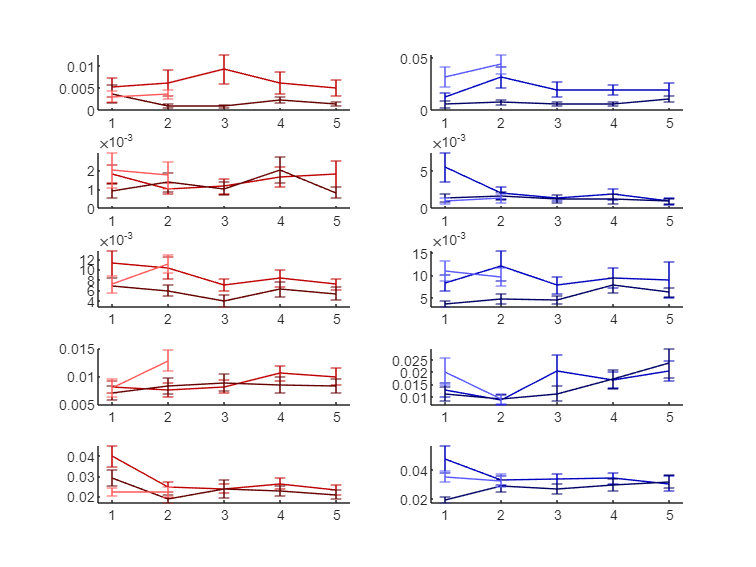

interaction type 1, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         1.9833      1       1.9833     50.605    3.5986e-09    3.5986e-09    3.5986e-09    3.5986e-09
    Error                               1.9988     51     0.039192                                                                   
    (Intercept):exposureday           0.013091      4    0.0032726    0.58385       0.67468       0.66775       0.67468     

interaction type 2, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         0.91641      1      0.91641     57.143    7.1384e-10    7.1384e-10    7.1384e-10    7.1384e-10
    Error                                0.8179     51     0.016037                                                                   
    (Intercept):exposureday           0.0092446      4    0.0023111    0.52989       0.71389       0.69758       0.71245

interaction type 3, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                         10.139      1       10.139    243.09    4.8122e-21    4.8122e-21    4.8122e-21    4.8122e-21
    Error                                2.127     51     0.041707                                                                  
    (Intercept):exposureday           0.059227      4     0.014807    1.8243       0.12546       0.14601       0.14184       0.1

interaction type 4, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         14.455      1       14.455     484.35    1.0708e-27    1.0708e-27    1.0708e-27    1.0708e-27
    Error                               1.5221     51     0.029845                                                                   
    (Intercept):exposureday           0.037817      4    0.0094542     1.8079       0.12862       0.14127       0.13616     

interaction type 5, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                          37.636      1       37.636     1205.5    3.7048e-37    3.7048e-37    3.7048e-37    3.7048e-37
    Error                                1.5922     51     0.031219                                                                   
    (Intercept):exposureday            0.076029      4     0.019007     3.5568     0.0078922      0.017274      0.015116

interaction type 1, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                         7.1257      1      7.1257    85.728    8.4693e-12    8.4693e-12    8.4693e-12    8.4693e-12
    Error                               3.5742     43     0.08312                                                                  
    (Intercept):exposureday            0.07287      4    0.018218    1.2596       0.28784       0.29065       0.28979       0.26796


a = 0

b = 0.1318

a2 = 1

b2 = 0.0159

a2 = 0

b3 = 0.0656

a2 = 1

b4 = 0.0097

a2 = 0

b5 = 0.1639

ans = 1×5 logical array
   0   1   0   1   0


interaction type 2, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                        0.79744      1      0.79744    45.761    2.8229e-08    2.8229e-08    2.8229e-08    2.8229e-08
    Error                              0.74933     43     0.017426                                                                  
    (Intercept):exposureday            0.04502      4     0.011255    2.6122      0.037154      0.045708      0.040269       0.1

interaction type 3, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         7.6648      1       7.6648     271.16    3.4982e-20    3.4982e-20    3.4982e-20    3.4982e-20
    Error                               1.2155     43     0.028266                                                                   
    (Intercept):exposureday           0.012189      4    0.0030472    0.26694        0.8989       0.89475        0.8989     

interaction type 4, sex 2

ans = 8×8 table
                                        SumSq       DF       MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                      __________    ___    __________    ________    __________    __________    __________    __________

    (Intercept)                           13.462      1        13.462      177.43    7.3543e-17    7.3543e-17    7.3543e-17    7.3543e-17
    Error                                 3.2625     43      0.075872                                                                    
    (Intercept):exposureday              0.46038      4        0.1151      9.9036    3.1014e-07    3.3078e-0

a = 0

b = 0.4829

interaction type 5, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         37.177      1       37.177       2178    1.8012e-38    1.8012e-38    1.8012e-38    1.8012e-38
    Error                              0.73398     43     0.017069                                                                   
    (Intercept):exposureday           0.006497      4    0.0016243    0.23889       0.91603       0.88362       0.89815     

figure
clear tbl
for j = 1:2

    if j == 1
    degutableT = degutable;
    colorcodesT = colorcodes_f;
    else
        degutableT = degutableM;
        colorcodesT = colorcodes_m;
    end
    
for i = 1:5
    
    
    allbyday = cat(3,degutableT(:,6:10,i), degutableT(:,11:15,i)).^(1/3);
    
    fprintf('interaction type %d, sex %d', i, j)
    tbl{i,j} = simple_mixed_anova(allbyday, [], {'exposureday' 'cagstr'});
    tbl{i,j}

    subplot(5,2,j+(i-1)*2);

    e1 = errorbar(1:5, nanmean(degutableT(:,11:15, i)), nanstd(degutableT(:,11:15,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(1,:));
    hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
    e2 = errorbar(1:5, nanmean(degutableT(:,6:10,i)), nanstd(degutableT(:,6:10,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

    errorbar(1:2, nanmean(degutableT(:,16:17,i)), nanstd(degutableT(:,16:17,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(3,:));

%    errorbar(6:7, nanmean(degutable(:,21:22,i)), nanstd(degutable(:, 21:22,i)/sqrt(length(degutable)-1)), 'r');
%    errorbar(8:9, nanmean(degutable(:,23:24,i)), nanstd(degutable(:, 23:24,i)/sqrt(length(degutable)-1)), 'r');

    set(get(e1, 'parent'), 'XLim', [0.75 5.25])
    box off
    
    if i == 4 & j == 2
        [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
    elseif i == 1 & j == 2
        [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
        [a2 b2] = ttest(degutableT(:,7,i) - degutableT(:,12,i))
        [a2 b3] = ttest(degutableT(:,8,i) - degutableT(:,13,i))
        [a2 b4] = ttest(degutableT(:,9,i) - degutableT(:,14,i))
        [a2 b5] = ttest(degutableT(:,10,i) - degutableT(:,15,i))
        fdr_bh([b b2 b3 b4 b5])
    end
    
    
 % 
end
end

figure
clear tbl
%for j = 1:2
j = 1

j = 1

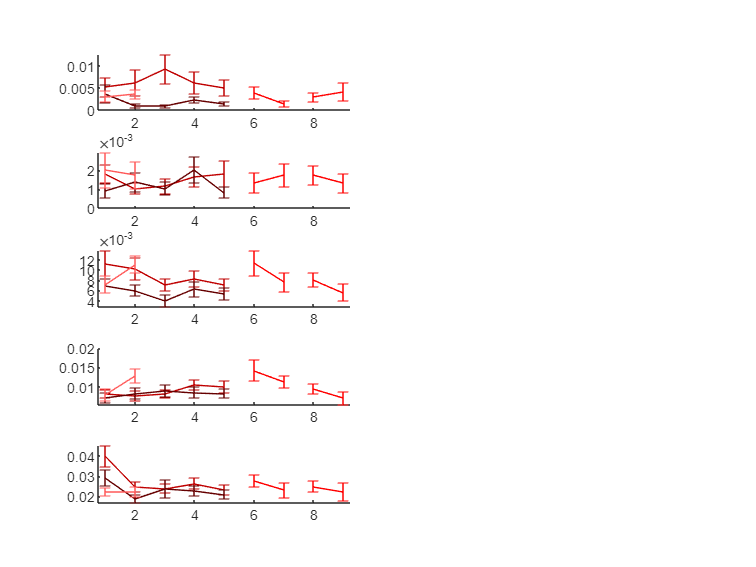

interaction type 1, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         1.9833      1       1.9833     50.605    3.5986e-09    3.5986e-09    3.5986e-09    3.5986e-09
    Error                               1.9988     51     0.039192                                                                   
    (Intercept):exposureday           0.013091      4    0.0032726    0.58385       0.67468       0.66775       0.67468     

interaction type 2, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         0.91641      1      0.91641     57.143    7.1384e-10    7.1384e-10    7.1384e-10    7.1384e-10
    Error                                0.8179     51     0.016037                                                                   
    (Intercept):exposureday           0.0092446      4    0.0023111    0.52989       0.71389       0.69758       0.71245

interaction type 3, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                         10.139      1       10.139    243.09    4.8122e-21    4.8122e-21    4.8122e-21    4.8122e-21
    Error                                2.127     51     0.041707                                                                  
    (Intercept):exposureday           0.059227      4     0.014807    1.8243       0.12546       0.14601       0.14184       0.1

interaction type 4, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         14.455      1       14.455     484.35    1.0708e-27    1.0708e-27    1.0708e-27    1.0708e-27
    Error                               1.5221     51     0.029845                                                                   
    (Intercept):exposureday           0.037817      4    0.0094542     1.8079       0.12862       0.14127       0.13616     

interaction type 5, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                          37.636      1       37.636     1205.5    3.7048e-37    3.7048e-37    3.7048e-37    3.7048e-37
    Error                                1.5922     51     0.031219                                                                   
    (Intercept):exposureday            0.076029      4     0.019007     3.5568     0.0078922      0.017274      0.015116

    if j == 1
    degutableT = degutable;
    colorcodesT = colorcodes_f;
    else
        degutableT = degutableM;
        colorcodesT = colorcodes_m;
    end
    
for i = 1:5
    
    
    allbyday = cat(3,degutableT(:,6:10,i), degutableT(:,11:15,i)).^(1/3);
    
    fprintf('interaction type %d, sex %d', i, j)
    tbl{i,j} = simple_mixed_anova(allbyday, [], {'exposureday' 'cagstr'});
    tbl{i,j}

    subplot(5,2,j+(i-1)*2);

    e1 = errorbar(1:5, nanmean(degutableT(:,11:15, i)), nanstd(degutableT(:,11:15,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(1,:));
    hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
    e2 = errorbar(1:5, nanmean(degutableT(:,6:10,i)), nanstd(degutableT(:,6:10,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

    errorbar(1:2, nanmean(degutableT(:,16:17,i)), nanstd(degutableT(:,16:17,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(3,:));

    errorbar(6:7, nanmean(degutable(:,21:22,i)), nanstd(degutable(:, 21:22,i)/sqrt(length(degutable)-1)), 'r');
    errorbar(8:9, nanmean(degutable(:,23:24,i)), nanstd(degutable(:, 23:24,i)/sqrt(length(degutable)-1)), 'r');

    set(get(e1, 'parent'), 'XLim', [0.75 9.25])
    box off
    
%     if i == 4 & j == 2
%         [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
%     elseif i == 1 & j == 2
%         [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
%         [a2 b2] = ttest(degutableT(:,7,i) - degutableT(:,12,i))
%         [a2 b3] = ttest(degutableT(:,8,i) - degutableT(:,13,i))
%         [a2 b4] = ttest(degutableT(:,9,i) - degutableT(:,14,i))
%         [a2 b5] = ttest(degutableT(:,10,i) - degutableT(:,15,i))
%         fdr_bh([b b2 b3 b4 b5])
%     end
    
    
 % 
%end
end

## III. Individual variation in SvC differences

*Here we find that only the 30% "significant" animals show the stranger vs. cagemate effect. Note that no animals were found to be significant in the other direction (higher in cagemate interactions).*

Repeat for only significant and only non-significant groups

for j = 1:2
    if j == 1
        dttT = dtt;
        indsigT = indsig;
        indnonsigT = indnonsig;
    else
        dttT = dttM;
        indsigT = indsigM;
        indnonsigT = indnonsigM;
    end

allbyday = [dttT(indsigT, 6:10) ; dtt(indsigT, 11:15)].^(1/3);
daymat = repmat(1:5, length(indsigT)*2, 1);
dyadmat = repmat(1:length(indsigT)', 2, 5);
cagVstr = [zeros(size(indsigT,1), 5) ; ones(length(indsigT), 5)];

%anovacell{1} = reshape(allbyday, [],1);
%anovacell{2} = reshape(daymat, [], 1);
%anovacell{3} = reshape(dyadmat, [],1);
%anovacell{4} = reshape(cagVstr, [],1);

%[B, BINT, R, RINT, STATS] = regress(anovacell{1}, [ones(length(anovacell{1}),1) anovacell{2} anovacell{4} anovacell{2}.*anovacell{4}]);
%B
%BINT

abd2 = cat(3,dttT(indsigT, 6:10) , dttT(indsigT, 11:15)).^(1/3);

fprintf('sig -- sex: %d', j)
tbl = simple_mixed_anova(abd2, [], {'exposureday' 'cagstr'}) 


allbyday = [dttT(indnonsigT, 6:10) ; dtt(indnonsigT, 11:15)].^(1/3);
daymat = repmat(1:5, length(indnonsigT)*2, 1);
dyadmat = repmat(1:length(indnonsigT)', 2, 5);
cagVstr = [zeros(size(indnonsigT,1), 5) ; ones(length(indnonsigT), 5)];

% anovacell{1} = reshape(allbyday, [],1);
% anovacell{2} = reshape(daymat, [], 1);
% anovacell{3} = reshape(dyadmat, [],1);
% anovacell{4} = reshape(cagVstr, [],1);
% 
% [B, BINT, R, RINT, STATS] = regress(anovacell{1}, [ones(length(anovacell{1}),1) anovacell{2} anovacell{4} anovacell{2}.*anovacell{4}]);
% 
% B

%BINT

abd2 = cat(3,dttT(indnonsigT, 6:10) , dttT(indnonsigT, 11:15)).^(1/3);
fprintf('nonsig -- sex: %d', j)
tbl = simple_mixed_anova(abd2, [], {'exposurday' 'cagstr'}) 
    end

sig -- sex: 1

tbl = 8×8 table
                                       SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                         19.703     1       19.703      463.6    1.0805e-12    1.0805e-12    1.0805e-12    1.0805e-12
    Error                              0.63749    15     0.042499                                                                   
    (Intercept):exposureday           0.023884     4     0.005971    0.89215       0.47431       0.44126       0.45714       0.3

nonsig -- sex: 1

tbl = 8×8 table
                                       SumSq       DF       MeanSq          F         pValue      pValueGG     pValueHF     pValueLB 
                                     __________    ___    __________    _________    _________    _________    _________    _________

    (Intercept)                           37.77      1         37.77       776.18    1.768e-25    1.768e-25    1.768e-25    1.768e-25
    Error                                1.7031     35      0.048661                                                                 
    (Intercept):exposurday             0.038806      4     0.0097016       1.5789      0.18322      0.20197      0.19778    

sig -- sex: 2

tbl = 8×8 table
                                       SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                         14.647     1       14.647     662.66    9.7069e-10    9.7069e-10    9.7069e-10    9.7069e-10
    Error                              0.19894     9     0.022104                                                                   
    (Intercept):exposureday            0.01613     4    0.0040326    0.46157       0.76339       0.72581       0.76339       0.5

nonsig -- sex: 2

tbl = 8×8 table
                                      SumSq      DF      MeanSq        F        pValue      pValueGG     pValueHF     pValueLB 
                                     ________    ___    _________    ______    _________    _________    _________    _________

    (Intercept)                        48.945      1       48.945      1081    8.455e-27    8.455e-27    8.455e-27    8.455e-27
    Error                              1.4941     33     0.045276                                                              
    (Intercept):exposurday           0.037616      4    0.0094039    0.9894      0.41573      0.40287      0.40857      0.32713
    Error(ex

## IV. Use individual variation to interpret new cagemates and new strangers

*Here we run the analyses on new cagemates and new strangers*

Reminder of the variables. Note that nst is the combination of both new stranger sessions, and so-on across other

% for i = 1:size(dtt,1)
%     [h(i),p(i)] = ttest2(dtt(i,6:10).^(1/3), dtt(i,11:15).^(1/3));
%     svc(i) = nanmean(dtt(i,11:15).^(1/3) - dtt(i,6:10).^(1/3)); 
%     cag(i) = nanmean(dtt(i,6:10).^(1/3));
%     str(i) = nanmean(dtt(i,11:15).^(1/3));
%     nst(i) = nanmean(dtt(i,16:17).^(1/3));
%     ncg(i) = nanmean(dtt(i,21:25).^(1/3));
%     nc1(i) = nanmean(dtt(i,21:22).^(1/3));
%     nc2(i) = nanmean(dtt(i,23:24).^(1/3));
% end

New strangers differ from cagemates:


[a, b, ~, st] = ttest(nst(indsig)-cag(indsig))

a = 1

b = 8.1761e-04

st = struct with fields:
    tstat: 4.1722
       df: 15
       sd: 0.0818


New strangers not different from old strangers:

[a, b, ~, st] = ttest(nst(indsig)-str(indsig))

a = 0

b = 0.2772

st = struct with fields:
    tstat: -1.1277
       df: 15
       sd: 0.0854


Strangers DO NOT differ from new cagemates:

notnanncg = intersect(indsig, find(~isnan(nc1)));

[a, b, ~, st] = ttest(str(notnanncg)-ncg(notnanncg))

a = 0

b = 0.6677

st = struct with fields:
    tstat: -0.4438
       df: 9
       sd: 0.0395


Cagemates differ from new cagemates

[a, b, ~, st] = ttest(cag(notnanncg)-ncg(notnanncg))

a = 1

b = 3.8008e-04

st = struct with fields:
    tstat: -5.5002
       df: 9
       sd: 0.0527


Strangers DO NOT differ from 1 week co-housed new cagemates

notnanncg2 = intersect(indsig, find(~isnan(nc2)));

[a, b, ~, st] = ttest(str(indsig)-nc2(indsig))

a = 0

b = 0.5114

st = struct with fields:
    tstat: 0.6917
       df: 7
       sd: 0.0477


Cagemates differ from 1 week co-housed new cagemates

[a, b, ~, st] = ttest(cag(notnanncg2)-nc2(notnanncg2))

a = 1

b = 0.0206

st = struct with fields:
    tstat: -2.9777
       df: 7
       sd: 0.0673


#### Males

Only need to test new strangers 

[a, b, ~, st] = ttest(cag_m-nst_m)

a = 1

b = 6.6561e-06

st = struct with fields:
    tstat: -5.1277
       df: 43
       sd: 0.1022


[a, b, ~, st] = ttest(str_m-nst_m)

a = 0

b = 0.0859

st = struct with fields:
    tstat: -1.7575
       df: 43
       sd: 0.1005


## V. Figures taking into account individual variation (females only)

Note: colorcodes on later figures need to be changed to colorcodes_f

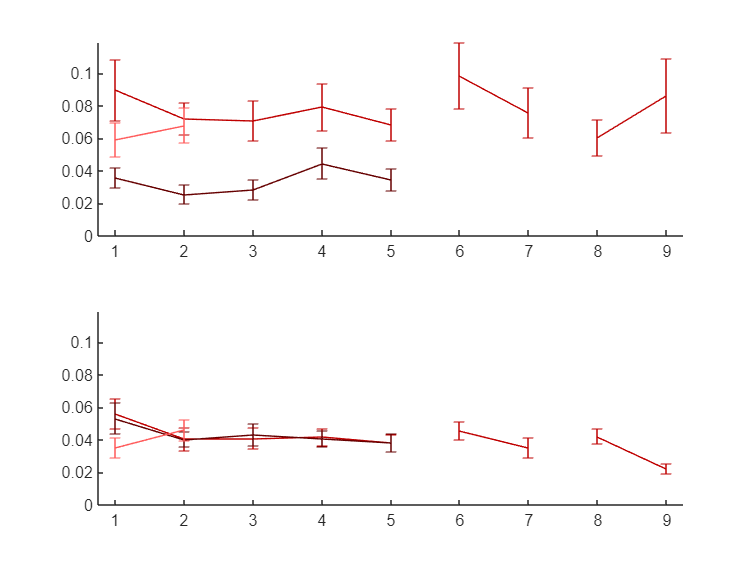

figure
subplot(2,1,1)
e1 = errorbar(1:5, nanmean(dtt(indsig,11:15)), nanstd(dtt(indsig,11:15))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indsig,6:10)), nanstd(dtt(indsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(1:2, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indsigM,11:15)), nanstd(dttM(indsigM,11:15))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%e2 = errorbar(1:5, nanmean(dttM(indsigM,6:10)), nanstd(dttM(indsigM,6:10))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dttM(indsigM,16:17)), nanstd(dttM(indsigM,16:17))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(3,:))



errorbar(6:7, nanmean(dtt(indsig,21:22)), nanstd(dtt(indsig, 21:22)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indsig,23:24)), nanstd(dtt(indsig, 23:24)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 9.25])
ylims = get(get(e1, 'parent'), 'YLim');
box off
subplot(2,1,2)
e1 = errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(1:2, nanmean(dtt(indnonsig,16:17)), nanstd(dtt(indnonsig,16:17))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indnonsigM,11:15)), nanstd(dttM(indnonsigM,11:15))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(1,:));
%hold on

%e2 = errorbar(1:5, nanmean(dttM(indnonsigM,6:10)), nanstd(dttM(indnonsigM,6:10))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(2,:));


%errorbar(1:2, nanmean(dttM(indnonsigM,16:17)), nanstd(dttM(indnonsigM,16:17))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(3,:))



errorbar(6:7, nanmean(dtt(indnonsig,21:22)), nanstd(dtt(indnonsig, 21:22)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indnonsig,23:24)), nanstd(dtt(indnonsig, 23:24)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
set(get(e1, 'parent'), 'XLim', [0.75 9.25])
set(get(e1, 'parent'), 'YLim', ylims);
box off

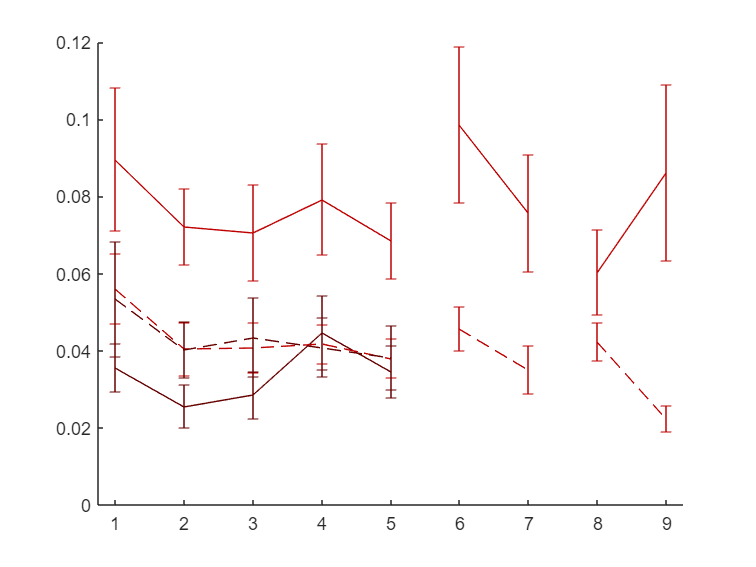

figure
e1 = errorbar(1:5, nanmean(dtt(indsig,11:15)), nanstd(dtt(indsig,11:15))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indsig,6:10)), nanstd(dtt(indsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'b')

errorbar(6:7, nanmean(dtt(indsig,21:22)), nanstd(dtt(indsig, 21:22)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indsig,23:24)), nanstd(dtt(indsig, 23:24)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));


e1 = errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'LineStyle', '--', 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:), 'LineStyle', '--');
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'b')

errorbar(6:7, nanmean(dtt(indnonsig,21:22)), nanstd(dtt(indnonsig, 21:22)/sqrt(length(indnonsig)-1)), 'LineStyle', '--','Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indnonsig,23:24)), nanstd(dtt(indnonsig, 23:24)/sqrt(length(indnonsig)-1)), 'LineStyle', '--','Color', colorcodes_fem(1,:));


set(get(e1, 'parent'), 'XLim', [0.75 9.25])
box off

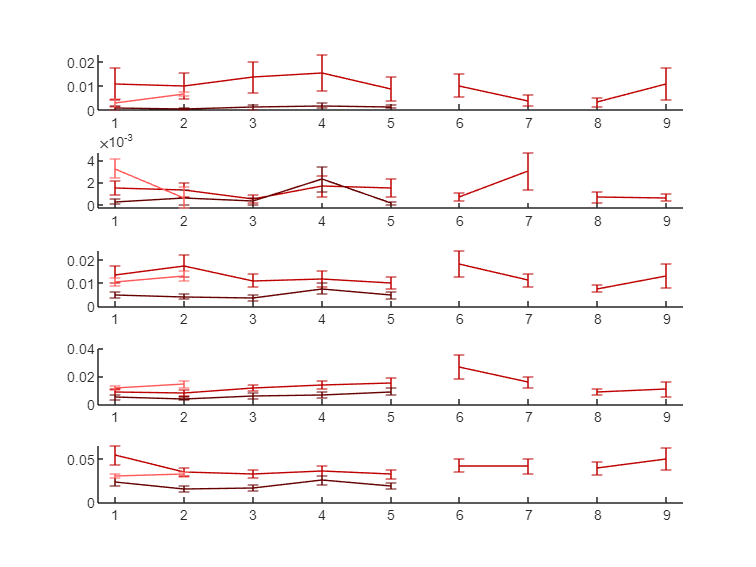


figure
for i = 1:5
    subplot(5,1,i)

e1 = errorbar(1:5, nanmean(degutable(indsig,11:15, i)), nanstd(degutable(indsig,11:15,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(degutable(indsig,6:10,i)), nanstd(degutable(indsig,6:10,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(1:2, nanmean(degutable(indsig,16:17,i)), nanstd(degutable(indnonsig,16:17,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:))

errorbar(6:7, nanmean(degutable(indsig,21:22,i)), nanstd(degutable(indsig, 21:22,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(degutable(indsig,23:24,i)), nanstd(degutable(indsig, 23:24,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 9.25])
box off
    
       
end

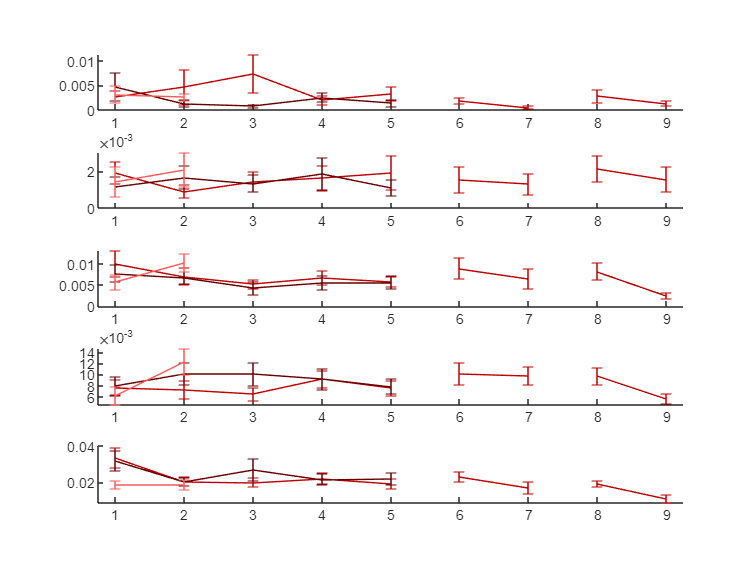




figure
for i = 1:5
    subplot(5,1,i)

e1 = errorbar(1:5, nanmean(degutable(indnonsig,11:15, i)), nanstd(degutable(indnonsig,11:15,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(degutable(indnonsig,6:10,i)), nanstd(degutable(indnonsig,6:10,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(1:2, nanmean(degutable(indnonsig,16:17,i)), nanstd(degutable(indnonsig,16:17,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:))

errorbar(6:7, nanmean(degutable(indnonsig,21:22,i)), nanstd(degutable(indnonsig, 21:22,i)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(degutable(indnonsig,23:24,i)), nanstd(degutable(indnonsig, 23:24,i)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 9.25])
box off
    
       
end


for i = 1:5
    [a b(i)] = ttest(degutable(indnonsig, 5+i, 1) - degutable(indnonsig,10+i,1));
end
b

## VI. Individual differences across interaction types

*Quick comparison across interaction types. Figures are misleading because do not take into account that only a subset of animals were 1-week co-housed as new strangers. Stats are more informative. *

Are new cagemates high levels of interaction because they're relying on different interaction types?

h = nan(size(dtt,1),1);
p = h;
clear cag3 str3 ncg3 nc13 nc23

for j = 1:size(degutable,3)
for i = 1:size(dtt,1)
%    [h(i),p(i)] = ttest2(degutable(i,6:10,j).^(1/3), degutable(i,11:15,j).^(1/3));
    svc3(i,j) = nanmean(squeeze(degutable(i,11:15,j))'.^(1/3) - squeeze(degutable(i,6:10,j))'.^(1/3)); 
    cag3(i,j) = nanmean(squeeze(degutable(i,6:10,j))'.^(1/3));
    str3(i,j) = nanmean(squeeze(degutable(i,11:15,j))'.^(1/3));
    nst3(i,j) = nanmean(squeeze(degutable(i,16:17,j))'.^(1/3));
    ncg3(i,j) = nanmean(squeeze(degutable(i,21:25,j))'.^(1/3));
    nc13(i,j) = nanmean(squeeze(degutable(i,21:22,j))'.^(1/3));
    nc23(i,j) = nanmean(squeeze(degutable(i,23:24,j))'.^(1/3));
end


[a1(j), b1(j), ~, st1(j)] = ttest(nc13(indsig,j)-cag3(indsig,j))%
[a2(j), b2(j), ~, st2(j)] = ttest(nc13(indsig,j)-str3(indsig,j))%

[a3(j), b3(j), ~, st3(j)] = ttest(nc23(indsig,j)-cag3(indsig,j));
[a4(j), b4(j), ~, st4(j)] = ttest(nc23(indsig,j)-str3(indsig,j));

end

a1 = 0

b1 = 0.2907

st1 = struct with fields:
    tstat: 1.1224
       df: 9
       sd: 0.1160


a2 = 0

b2 = 0.8157

st2 = struct with fields:
    tstat: -0.2400
       df: 9
       sd: 0.1382


a1 =      0     0


b1 =     0.2907    0.0862


st1 = 1×2 struct array with fields:
    tstat
    df
    sd


a2 =      0     0


b2 =     0.8157    0.5736


st2 = 1×2 struct array with fields:
    tstat
    df
    sd


a1 =      0     0     1


b1 =     0.2907    0.0862    0.0112


st1 = 1×3 struct array with fields:
    tstat
    df
    sd


a2 =      0     0     0


b2 =     0.8157    0.5736    0.6028


st2 = 1×3 struct array with fields:
    tstat
    df
    sd


a1 =      0     0     1     0


b1 =     0.2907    0.0862    0.0112    0.0792


st1 = 1×4 struct array with fields:
    tstat
    df
    sd


a2 =      0     0     0     0


b2 =     0.8157    0.5736    0.6028    0.3932


st2 = 1×4 struct array with fields:
    tstat
    df
    sd


a1 =      0     0     1     0     1


b1 =     0.2907    0.0862    0.0112    0.0792    0.0007


st1 = 1×5 struct array with fields:
    tstat
    df
    sd


a2 =      0     0     0     0     0


b2 =     0.8157    0.5736    0.6028    0.3932    0.4646


st2 = 1×5 struct array with fields:
    tstat
    df
    sd


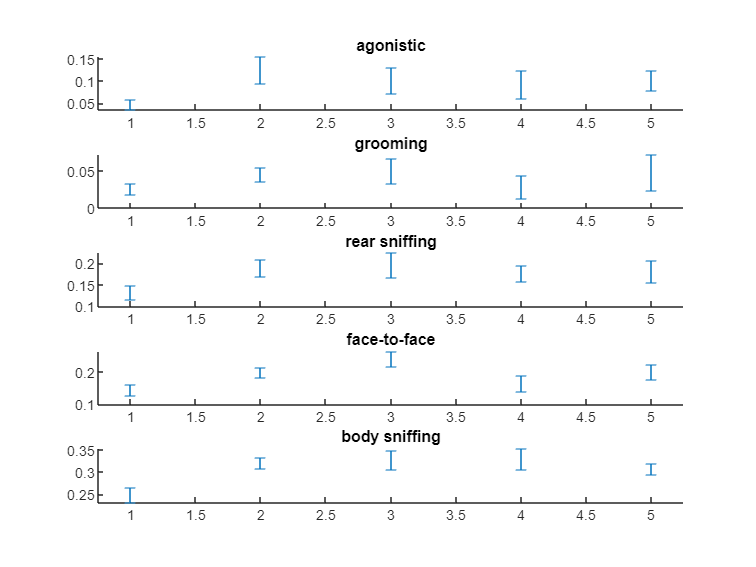

titlecell = {'agonistic', 'grooming', 'rear sniffing', 'face-to-face', 'body sniffing'};
figure
for j = 1:5
    a = subplot(5,1,j);
    errorbar(nanmean([cag3(indsig,j) str3(indsig,j) nc13(indsig,j) nc23(indsig,j) nst3(indsig,j)]), nanstd([cag3(indsig,j) str3(indsig,j) nc13(indsig,j) nc23(indsig,j) nst3(indsig,j)])/sqrt(length(indsig)-1), 'LineStyle', 'none' );
    
%       set(d, 'XLim', [.75 5.25]);
   title(titlecell{j});
   box off
   set(a, 'Xlim', [0.75 5.25]);
end

## VII. Create a figure of variability across individuals/sessions

%female first

cumsumbehavID = Rdb_CumSum2(rdb_rr, betypes, 0);
mk_cumsumtable; %female degu table but with cumsums (note it's 4D)


%here we are creating tables that show which interaction a degu was
%performing at a given point of each session
cdsum_cag = nan(size(cumdegutable,1), 5*size(cumdegutable,3)-5);
cdsum_str = nan(size(cumdegutable,1), 5*size(cumdegutable,3)-5);

for i = 1:size(cumdegutable,1)
    for j = 1:5 
        dcum_cag = diff(squeeze(cumdegutable(i,5+j,:,:))); %cumsums are cumulative, so have to take the derivative 
        dcum_str = diff(squeeze(cumdegutable(i,10+j,:,:)));
        
         a = repmat(1:5, size(dcum_cag,1),1); %doesn't matter "how much" they were performing that interaction during the time bin, only matters if they were performing it at all
         dcumT = dcum_cag > 0;
         dcumC_cag = dcumT .* a;     
         
         a = repmat(1:5, size(dcum_str,1),1);
         dcumT = dcum_str > 0;
         dcumC_str = dcumT .* a; 
        
         dcumC_cag(dcumC_cag == 0) = nan;
         dcumC_str(dcumC_str == 0) = nan;
        
         cdinds = ((j-1)*600)+(1:600);
         
         cdsum_cag(i,cdinds) = nanmin(dcumC_cag, [], 2); %If there is more than one interaction during a time bin, we prioritize by the following: agonistic > grooming > rear-sniffing > face-face > body sniffing
        cdsum_str(i,cdinds) = nanmin(dcumC_str, [], 2);

    end
end
    cdsum_cag(isnan(cdsum_cag)) = 0;
    cdsum_str(isnan(cdsum_str)) = 0;


        
 %   dcum = dcum+[zeros(1,scb) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,scb)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors

% Cd_cell = cell(2,1);
% for j = 1:2
%     if j == 1
%         p_airs = fem_pairs;
%     elseif j == 2
%         p_airs = mal_pairs;
%     end
%     for i = 1:length(p_airs)
%         for k = 1:5
%            cd_inds = ((k-1) * 600)+(1:600);
%            curind = find(rdb_rr.exposurenum' == k & rdb_rr.paircode == p_airs(i)); 
%            if ~isempty(curind)
%                 Cd_cell{j}(i,cd_inds) = Cdsum(curind(1), :);   
%            end
%         end
%     end
%     
% end

Figures of variability across sessions

peakag = nan(size(cdsum_cag,1), 2);
for i = 1:length(peakag)
    for j = 1:2
        if j == 1
          ag = cdsum_cag(i,:) == 1;
          alint = cdsum_cag(i,:) > 0;
        elseif j == 2
          ag = cdsum_str(i,:) == 1;
          alint = cdsum_str(i,:) > 0;
        end
      cdsmooth = fastsmooth(ag, 10, 2);
      cdsmoothall = fastsmooth(alint, 10, 2);
      [~, peakag(i,j)] = max(cdsmooth);
      [~, peakall(i,j)] = max(cdsmoothall);
        
    end
end

%repeat for male

%cumsumbehavID = Rdb_CumSum(rdb_rr, betypes, 0);
mk_cumsumtable_m; %female degu table but with cumsums (note it's 4D)


%here we are creating tables that show which interaction a degu was
%performing at a given point of each session
cdsum_cagM = nan(size(cumdegutableM,1), 5*size(cumdegutableM,3)-5);
cdsum_strM = nan(size(cumdegutableM,1), 5*size(cumdegutableM,3)-5);

for i = 1:size(cumdegutableM,1)
    for j = 1:5 
        dcum_cagM = diff(squeeze(cumdegutableM(i,5+j,:,:))); %cumsums are cumulative, so have to take the derivative 
        dcum_strM = diff(squeeze(cumdegutableM(i,10+j,:,:)));
        
         a = repmat(1:5, size(dcum_cagM,1),1); %doesn't matter "how much" they were performing that interaction during the time bin, only matters if they were performing it at all
         dcumTM = dcum_cagM > 0;
         dcumC_cagM = dcumTM .* a;     
         
         a = repmat(1:5, size(dcum_strM,1),1);
         dcumTM = dcum_strM > 0;
         dcumC_strM = dcumTM .* a; 
         
         
         dcumC_cagM(dcumC_cagM == 0) = nan;
         dcumC_strM(dcumC_strM == 0) = nan;
         
         cdinds = ((j-1)*600)+(1:600);
        
         cdsum_cagM(i,cdinds) = nanmin(dcumC_cagM, [], 2); %If there is more than one interaction during a time bin, we prioritize by the following: agonistic > grooming > rear-sniffing > face-face > body sniffing
        cdsum_strM(i,cdinds) = nanmin(dcumC_strM, [], 2);

    end
end

cdsum_cagM(isnan(cdsum_cagM)) = 0;
cdsum_strM(isnan(cdsum_strM)) = 0;
        
 %   dcum = dcum+[zeros(1,scb) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,scb)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors

% Cd_cell = cell(2,1);
% for j = 1:2
%     if j == 1
%         p_airs = fem_pairs;
%     elseif j == 2
%         p_airs = mal_pairs;
%     end
%     for i = 1:length(p_airs)
%         for k = 1:5
%            cd_inds = ((k-1) * 600)+(1:600);
%            curind = find(rdb_rr.exposurenum' == k & rdb_rr.paircode == p_airs(i)); 
%            if ~isempty(curind)
%                 Cd_cell{j}(i,cd_inds) = Cdsum(curind(1), :);   
%            end
%         end
%     end
%     
% end

Figures of variability across sessions

peakagM = nan(size(cdsum_cagM,1), 2);
for i = 1:length(peakagM)
    for j = 1:2
        if j == 1
          ag = cdsum_cagM(i,:) == 1;
          alint = cdsum_cagM(i,:) > 0;
        elseif j == 2
          ag = cdsum_strM(i,:) == 1;
          alint = cdsum_strM(i,:) > 0;
        end
      cdsmooth = fastsmooth(ag, 15, 1);
      cdsmoothall = fastsmooth(alint, 15, 1);
      [~, peakagM(i,j)] = max(cdsmooth);      
      [~, peakallM(i,j)] = max(cdsmoothall);
      
    end
end

Set-up order for the figure (later peak interactions descenting along the rows)

% top two panels will be female.
% both of the top two panels will be sorted by strangers (left)
    pa_nn = peakag(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorders] = sort(pa_nn);
    
    pa_nn = peakall(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorder2s] = sort(pa_nn);
        
    pa_nn = peakag(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderc] = sort(pa_nn);
    
    pa_nn = peakall(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorder2c] = sort(pa_nn);
    
    
   
%male 

    pa_nnM = peakagM(:,2);
    pa_nnM = pa_nnM(~isnan(pa_nnM));
    [b, sortorderMs] = sort(pa_nnM);
    
    pa_nn = peakallM(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderM2s] = sort(pa_nn);
    
    pa_nnM = peakagM(:,1);
    pa_nnM = pa_nnM(~isnan(pa_nnM));
    [b, sortorderMc] = sort(pa_nnM);
    
    pa_nn = peakallM(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderM2c] = sort(pa_nn);
    
    

Create the figure. Choose "sortorder" for agonistic-based sorting, "sortorder2" for all interactions

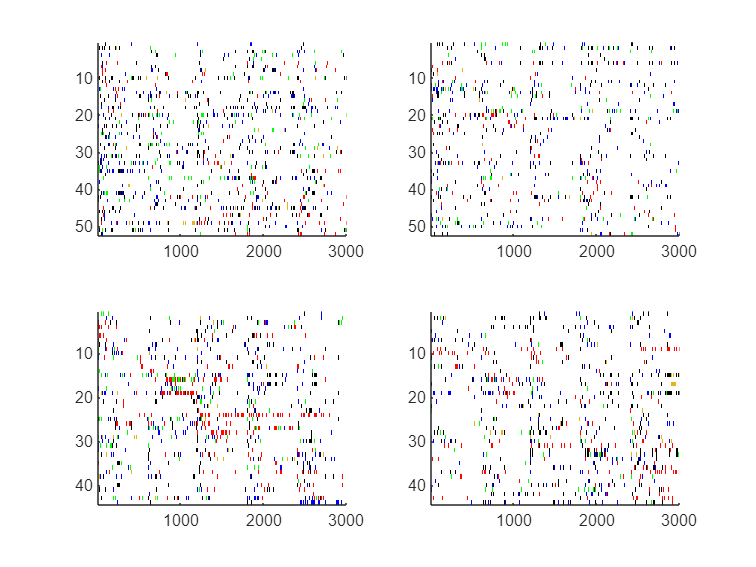


soFs = sortorders;
soMs = sortorderMs;

soFc = sortorderc;
soMc = sortorderMc;
    load colormap_white_discrete
%    load colormap_newcm
%for j = 1:2
 
new_cm = cnew;

figure
     subplot(2,2,1); 
    im_f = imagesc(cdsum_str(soFs, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

    subplot(2,2,2); 
    im_f = imagesc(cdsum_cag(soFc, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off    
    
 subplot(2,2,3); 
    im_f = imagesc(cdsum_strM(soMs, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

  subplot(2,2,4); 
    im_f = imagesc(cdsum_cagM(soMc, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

    %end
    
    
    
   

## Interaction levels across dates (not included)

*This provided the first evidence that we had to be concerned about individual variation. An important follow-up would be to evaluate experimenter effects. *


f = figure

f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 544 560 420]
       Units: 'pixels'

  Show all properties


hold

Current plot held


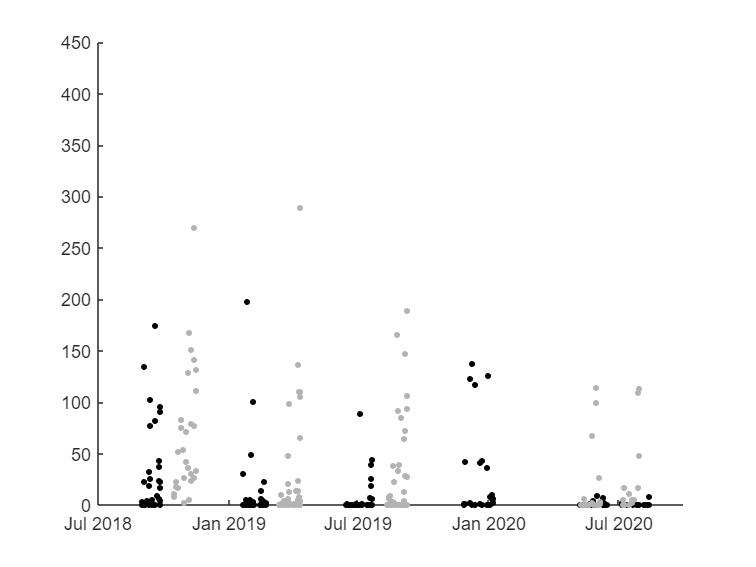

ag = nan(length(rdb_rr.deguA),1); 
for i = 1:length(rdb_rr.deguA)
    if rdb_rr.strangernum(i) > 0
        agint = find(rdb_rr.be_identcode(:,i) < -1 | strcmpi('avoid', rdb_rr.be_ident(:,i))); 
        ag(i) = sum(rdb_rr.be_start_end(agint,2,i)-rdb_rr.be_start_end(agint,1,i)); 
    end    
end
rdbdate = datetime(rdb_rr.date_session);
plot(rdbdate, ag, 'k.', 'MarkerSize', 10);
tind = find(strcmpi('M', rdb_rr.sex));
plot(rdbdate(tind), ag(tind), '.', 'Color', [.7 .7 .7], 'MarkerSize', 10);
set(get(f, 'Children'), 'YLim', [0 450]);
box off

%plot(rdbdate, ag, 'k.', 'MarkerSize', 10);
%tind = find(strcmpi('M', rdb_rr.sex));
%plot(rdbdate(tind), ag(tind), '.', 'Color', [.7 .7 .7], 'MarkerSize', 10);
%set(get(f, 'Children'), 'YLim', [0 450]);
%box off

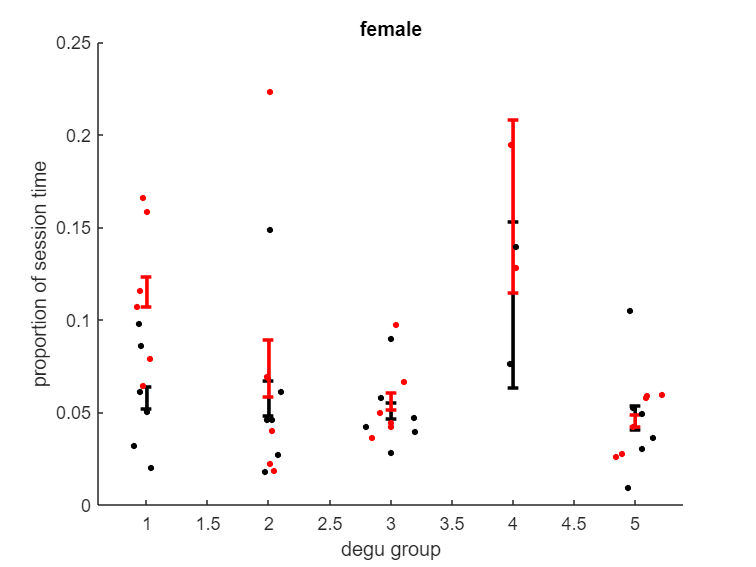



%split dates into 5 groups

dategroup{1} = find(rdb_rr.date_session(:,1) < 2019);
dategroup{2} = find(rdb_rr.date_session(:,1) == 2019 & rdb_rr.date_session(:,2) < 5);
dategroup{3} = find(rdb_rr.date_session(:,1) == 2019 & rdb_rr.date_session(:,2) > 5 & rdb_rr.date_session(:,2) < 11);
dategroup{4} = find((rdb_rr.date_session(:,1) == 2019 & rdb_rr.date_session(:,2) > 10) | (rdb_rr.date_session(:,1) == 2020 & rdb_rr.date_session(:,2) < 3));
%dategroup{5} = find(rdb_rr.date_session(:,1) == 2020 & rdb_rr.date_session(:,2) > 3); 


for j = 1; %save males for later
if j == 1
    pairs = fem_pairs;
    cmat = conditionmat_f;
    title_group = 'female';
elseif j == 2
    pairs = mal_pairs;
    cmat = conditionmat_m;
    title_group = 'male';
end
clear cagm ostr
cmatsum = nanmean(squeeze(nansum(cmat(:,:,1:5), 2)), 2); %first 5 sessions?
%  cmatsum = squeeze(nansum(conditionmat_f(:,:,3), 2));
  

cagm = nan(6,length(dategroup));
ostr = nan(6,length(dategroup));
clear cg_inds st_inds
for i = 1:length(dategroup)
    cur_pairnums_ind = find(ismember(pairs, unique(rdb_rr.paircode(dategroup{i}))));
    
    cg_inds{i} = intersect(cur_pairnums_ind, cagemates_f);
    l_c(i) = length(cg_inds{i});
    cagm(1:length(cg_inds{i}),i) = cmatsum(cg_inds{i}) ;
    
    st_inds{i} = intersect(cur_pairnums_ind, ostrangers_f);
    l_s(i) = length(st_inds{i});
    ostr(1:length(st_inds{i}),i) = cmatsum(st_inds{i}) ;             
end

f(j) = figure;

hold on

e1 = errorbar(1:length(dategroup), nanmean(cagm), nanstd(cagm)./(l_c-1), 'k', 'LineStyle', 'none');
e2 = errorbar(1:length(dategroup), nanmean(ostr), nanstd(ostr)./(l_s-1), 'r', 'LineStyle', 'none');
set(e1, 'LineWidth', 2);
set(e2, 'LineWidth', 2);


set(get(e1(j), 'Parent'), 'XLim', [.6 5.4]);
ah = get(e1(j), 'Parent');
set(get(ah, 'YLabel'), 'String', 'proportion of session time');
set(get(ah, 'XLabel'), 'String', 'degu group')
title(title_group);

cs = cat(1,cagm, ostr);

anovacell{1} = reshape(cs, size(cs,1) * size(cs,2), 1);
anovacell{2} = reshape([ones(size(cagm)) ; 2*ones(size(ostr))], size(cs,1) * size(cs,2), 1);
anovacell{3} = reshape(repmat(1:size(cs,2), size(cs,1),1), size(cs,1) * size(cs,2), 1);

indcag = find(anovacell{2} == 1);
indstr = find(anovacell{2} == 2);

esS1 = swarmchart(anovacell{3}(indcag), anovacell{1}(indcag), 12, 'k', 'filled');
set(esS1, 'XJitterWidth', 0.5);
esS2 = swarmchart(anovacell{3}(indstr), anovacell{1}(indstr), 12, 'r', 'filled');
set(esS2, 'XJitterWidth', 0.5);


end



%set(get(es1(j), 'Parent'), 'XLim', [.6 5.4]);
%ah = get(es1(j), 'Parent');
%set(get(ah, 'YLabel'), 'String', 'proportion of session time');
%set(get(ah, 'XLabel'), 'String', 'degu group')
title(title_group);

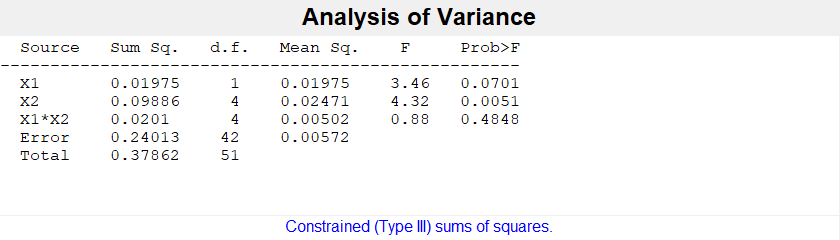




[p t s] = anovan(anovacell{1}.^(1/3), anovacell(2:3), 'model', 'interaction');